# Survey data analysis

Pie chart for regulation strategies

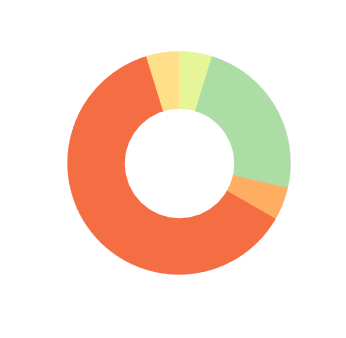

clear;
close all;
basedir = '/Users/clinpsywoo/github/CRB_project/MWW_inprep/scripts';
cd(basedir);

figdir = '../figures';
load('../data/CRB_reg_category.mat');

for i = 1:8
    k(i) = sum(reg_category.data(:,2) == i);
end

cols = [   0.1961    0.5333    0.7412
    0.8353    0.2431    0.3098
    0.3686    0.3098    0.6353
    0.9961    0.8784    0.5451
    0.9569    0.4275    0.2627
    0.9922    0.6824    0.3804
    0.6706    0.8667    0.6431
    0.9020    0.9608    0.5961];

h = wani_pie(k(k~=0), 'notext', 'hole', 'hole_size', 12000, 'cols', cols(k~=0, :));
set(gcf, 'position', [360   360   346   338], 'color', 'w');
savename = fullfile(figdir, 'Study1_reg_cat_up.pdf');

pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);


idx = find(k~=0);
pct = k/sum(k)*100;
for i = 1:numel(idx)
    fprintf('%s: %2.1f%%\n', reg_category.category{idx(i)}, pct(idx(i)));
end

4: Unpleasant imaginings: 4.8%


5: Dramatized coping: 61.9%


6: Rhythmic cognitive activity: 4.8%


7: Pain acknowledging: 23.8%


8: Breathing activity: 4.8%


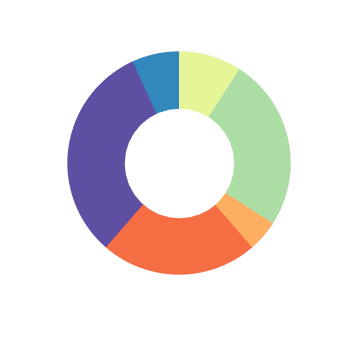

close all;
a = [reg_category.data(:,4); reg_category.data(:,5)];
for i = 1:8
    kk(i) = sum(a == i);
end

h = wani_pie(kk(kk~=0), 'notext', 'hole', 'hole_size', 12000, 'cols', cols(kk~=0, :));
set(gcf, 'position', [360   360   346   338], 'color', 'w');
savename = fullfile(figdir, 'Study1_reg_cat_down.pdf');

pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);


idx = find(kk~=0);
pct = kk/sum(kk)*100;
for i = 1:numel(idx)
    fprintf('%s: %2.1f%%\n', reg_category.category{idx(i)}, pct(idx(i)));
end

1: External focus of attention: 6.8%


3: Pleasant imaginings: 31.8%


5: Dramatized coping: 22.7%


6: Rhythmic cognitive activity: 4.5%


7: Pain acknowledging: 25.0%


8: Breathing activity: 9.1%


## Correlate the categories with the SCR marker response

basedir = '/Users/clinpsywoo/github/CRB_project/MWW_inprep/scripts';

cd(basedir);
load('../data/CRB_dataset_SCR_lpf5Hz_DS25Hz_011516.mat');
load('../data/SCR_prediction_dat_112816.mat');
load('../data/ECG_prediction_dat_112816.mat');
load('../data/CRB_reg_category.mat');

for i = 1:numel(D.Subj_Level.id)
    allsid(i,1) = str2num(D.Subj_Level.id{i}(:,4:6));
end

down_passive = cat(2,test_scr_int{:,1})-cat(2,test_scr_int{:,2});
up_passive = cat(2,test_scr_int{:,3})-cat(2,test_scr_int{:,2});
% down_up = cat(2,test_scr_int{:,2})-cat(2,test_scr_int{:,3});

% down_passive = cat(2,test_scr_unp{:,1})-cat(2,test_scr_unp{:,2});
% up_passive = cat(2,test_scr_unp{:,3})-cat(2,test_scr_unp{:,2});


sidx = ismember(allsid, reg_category.data(:,1));

downdat = [reg_category.data(:,4:5) down_passive(sidx, :)];

for i = 1:8
    x{i} = [];
    for j = 1:size(downdat,1)
        if any(downdat(j,1:2) == i)
            x{i}(end+1,:) = downdat(j,3:8);
        end
    end
end

updat = [reg_category.data(:,2) up_passive(sidx, :)];

for i = 1:8
    xx{i} = [];
    for j = 1:size(updat,1)
        if any(updat(j,1) == i)
            xx{i}(end+1,:) = updat(j,2:7);
        end
    end
end

for i = 1:numel(x)
    down_x1{i} = nanmean(x{i},2);
end

down_x2 = cellfun(@nanmean, down_x1, 'UniformOutput', false);
down_ste2 = cellfun(@ste, down_x1, 'UniformOutput', false);

down_x = cat(1,down_x2{:});
down_ste = cat(1,down_ste2{:});

for i = 1:numel(xx)
    up_x1{i} = nanmean(xx{i},2);
end

up_x2 = cellfun(@nanmean, up_x1, 'UniformOutput', false);
up_ste2 = cellfun(@ste, up_x1, 'UniformOutput', false);

up_x = cat(1,up_x2{:});
up_ste = cat(1,up_ste2{:});



## Bar plots for SCR

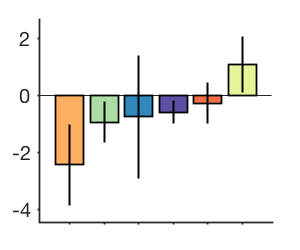


cols = [0.1961    0.5333    0.7412
    0.8353    0.2431    0.3098
    0.3686    0.3098    0.6353
    0.9961    0.8784    0.5451
    0.9569    0.4275    0.2627
    0.9922    0.6824    0.3804
    0.6706    0.8667    0.6431
    0.9020    0.9608    0.5961];


new_down_x = down_x(~isnan(down_x),:);
new_down_ste = down_ste(~isnan(down_x),:);
cols_down_x = cols(~isnan(down_x),:);
[~, idx] = sort(new_down_x);

bar_wani_2016(new_down_x(idx)', new_down_ste(idx)', .8, 'colors', cols_down_x(idx,:), 'errbar_width', 0);

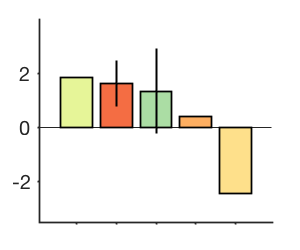


new_up_x = up_x(~isnan(up_x),:);
new_up_ste = up_ste(~isnan(up_x),:);
cols_up_x = cols(~isnan(up_x),:);
[~, idx] = sort(new_up_x, 'descend');

bar_wani_2016(new_up_x(idx)', new_up_ste(idx)', .8, 'colors', cols_up_x(idx,:), 'errbar_width', 0);

## ECG marker

% missing ECG data: 39th subject (245) 
allsid(allsid==245) = [];
reg_category.data = reg_category.data(reg_category.data(:,1)~=245,:);


down_passive = cat(2,test_ecg_int{:,1})-cat(2,test_ecg_int{:,2});
up_passive = cat(2,test_ecg_int{:,3})-cat(2,test_ecg_int{:,2});

% down_passive = cat(2,test_ecg_unp{:,1})-cat(2,test_ecg_unp{:,2});
% up_passive = cat(2,test_ecg_unp{:,3})-cat(2,test_ecg_unp{:,2});


% down_up = cat(2,test_scr_int{:,2})-cat(2,test_scr_int{:,3});

sidx = ismember(allsid, reg_category.data(:,1));

downdat = [reg_category.data(:,4:5) down_passive(sidx, :)];

for i = 1:8
    x{i} = [];
    for j = 1:size(downdat,1)
        if any(downdat(j,1:2) == i)
            x{i}(end+1,:) = downdat(j,3:8);
        end
    end
end

updat = [reg_category.data(:,2) up_passive(sidx, :)];

for i = 1:8
    xx{i} = [];
    for j = 1:size(updat,1)
        if any(updat(j,1) == i)
            xx{i}(end+1,:) = updat(j,2:7);
        end
    end
end

for i = 1:numel(x)
    down_x1{i} = nanmean(x{i},2);
end

down_x2 = cellfun(@nanmean, down_x1, 'UniformOutput', false);
down_ste2 = cellfun(@ste, down_x1, 'UniformOutput', false);

down_x = cat(1,down_x2{:});
down_ste = cat(1,down_ste2{:});

for i = 1:numel(xx)
    up_x1{i} = nanmean(xx{i},2);
end

up_x2 = cellfun(@nanmean, up_x1, 'UniformOutput', false);
up_ste2 = cellfun(@ste, up_x1, 'UniformOutput', false);

up_x = cat(1,up_x2{:});
up_ste = cat(1,up_ste2{:});


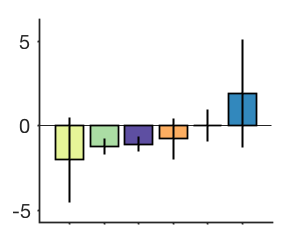


cols = [0.1961    0.5333    0.7412
    0.8353    0.2431    0.3098
    0.3686    0.3098    0.6353
    0.9961    0.8784    0.5451
    0.9569    0.4275    0.2627
    0.9922    0.6824    0.3804

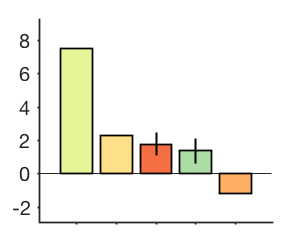

    0.6706    0.8667    0.6431
    0.9020    0.9608    0.5961];


new_down_x = down_x(~isnan(down_x),:);
new_down_ste = down_ste(~isnan(down_x),:);
cols_down_x = cols(~isnan(down_x),:);

[~, idx] = sort(new_down_x);

ans =     'col 4: ERQ Reappraisal avg'
    'col 5: ERQ Suppression avg'
    'col 6: PCS Total'


r =     0.2715
    0.1538
    0.0171


p =     0.0860
    0.3369
    0.9156



bar_wani_2016(new_down_x(idx)', new_down_ste(idx)', .8, 'colors', cols_down_x(idx,:), 'errbar_width', 0);

new_up_x = up_x(~isnan(up_x),:);
new_up_ste = up_ste(~isnan(up_x),:);
cols_up_x = cols(~isnan(up_x),:);
[~, idx] = sort(new_up_x, 'descend');

bar_wani_2016(new_up_x(idx)', new_up_ste(idx)', .8, 'colors', cols_up_x(idx,:), 'errbar_width', 0);
